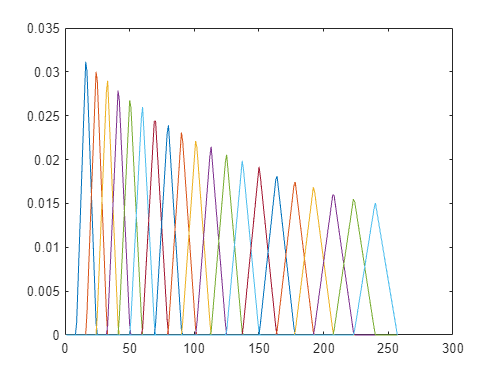

fb = designAuditoryFilterBank(POI.fs, ...
                                   "FFTLength",POI.Nfft, ...
                                   "NumBands",20, ...
                                   "FrequencyRange",[POI.f1, POI.f2])';

plot(fb);

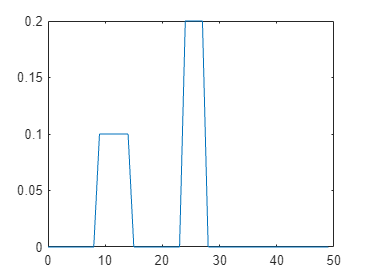

y = zeros(50, 1);
y(10:15) = 1/10;
y(25:28) = 2/10;
x = (0:49)';
plot(x, y)


centroid = sum(x.*y)/sum(y);
intertia = sqrt(sum(((x-centroid).^2).*y)/sum(y));


load store\Features.mat
feats = feats(feats.Dataset == 2, :);
[X, ev, explvar, npca, names, feats, eigvec, logcolnames] = POI.PrepareDataMatrixPCA(feats, 0.90);

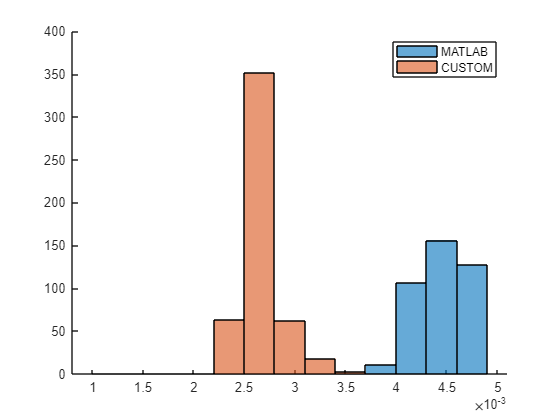

clear t1 t2
for i = 1:500   
tic
gmm = fitgmdist(Hw', 2,"RegularizationValue",0, 'Options',statset('Display','off','MaxIter',30,'TolFun',1e-6), 'Start','plus');
t1(i) = toc;
tic
[probs, mu_s, mu_ns, sigma_s, sigma_ns, pi_s, pi_ns, n_iter, converged, LL] = SignalDetection.gmmSE(Hw, 30);
t2(i) = toc;
end
figure
hold on
b = 1e-3:300e-6:5e-3;
histogram(t1, b)
histogram(t2, b)
hold off
legend("MATLAB", "CUSTOM")

disp(n_iter)

    22



disp(gmm.NumIterations)

    15



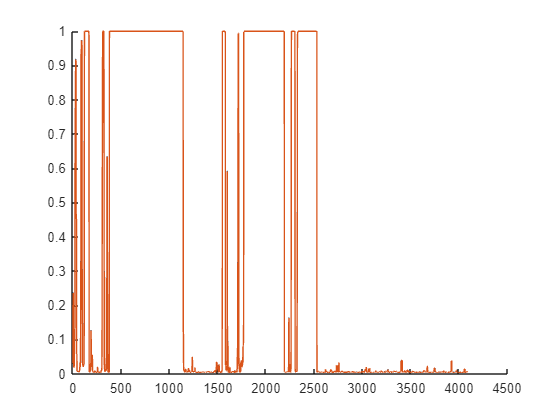

figure
hold on
plot(probs)
p = posterior(gmm, Hw');
plot(p(:,1))